% AMPLIACION DE ROBOTICA
% PRACTICA 4: Navegacion local con campos potenciales
% Evitar obstaculos

clc
clearvars
close all

## Carga del mapa de ocupacion

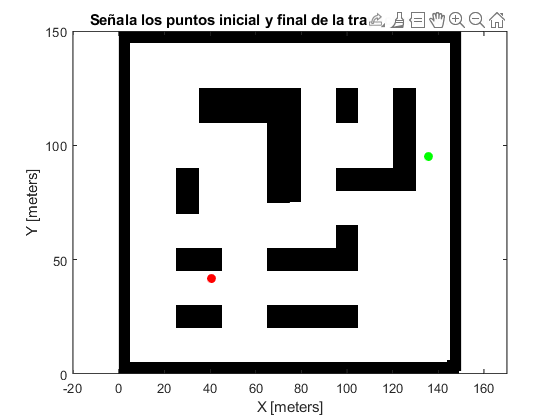

map_img=imread('mapa1_150.png');
map_neg=imcomplement(map_img);
map_bin=imbinarize(map_neg);
mapa=binaryOccupancyMap(map_bin);

figure; 
show(mapa);  % Mostrar el mapa
hold on;
axis equal;

% Marcar los puntos de inicio y destino

title('Señala los puntos inicial y final de la trayectoria del robot');
origen=ginput(1);
plot(origen(1), origen(2), 'go','MarkerFaceColor','green');  % Dibujamos el origen
destino=ginput(1);
plot(destino(1), destino(2), 'ro','MarkerFaceColor','red');  % Dibujamos el destino

% Configuracion del sensor (laser de barrido)
max_rango=10;
angulos=-pi/2:(pi/180):pi/2; % resolucion angular barrido laser

% Caracteristicas del vehiculo y parametros del metodo
v=0.4;            % Velocidad del robot
D=1.5;           % Rango del efecto del campo de repulsión de los obstáculos
alfa=10;           % Coeficiente de la componente de atracción
beta=100;      % Coeficiente de la componente de repulsión

## Inicialización

robot=[origen 0];     % El robot empieza en la posición de origen (orientacion cero)
path = [];                 % Se almacena el camino recorrido
path = [path; robot]; % Se añade al camino la posicion actual del robot
iteracion=0;              % Se controla el nº de iteraciones por si se entra en un minimo local

## Calculo de la trayectoria

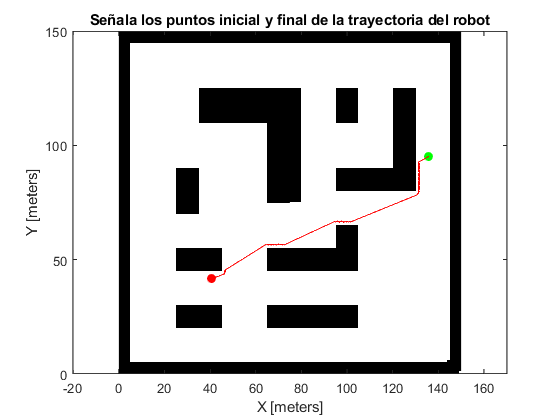

while norm(destino-robot(1:2)) > v && iteracion<1000    % Hasta menos de una iteración de la meta (10 cm)
    % TU CODIGO AQUI %%%%%%%%%%%%%
    % Cálculo de la fuerza de atracción
    dir_atrac = destino - robot(1:2);
    Fatrac = alfa * dir_atrac / norm(dir_atrac);  % Normalizar el vector de atracción

    % Simulación del sensor Lidar
    obs = SimulaLidar(robot, mapa, angulos, max_rango);
    
    % Inicializar la fuerza de repulsión
    Frepul = [0, 0];

    % Procesar cada obstáculo detectado
    for i = 1:size(obs, 1)
        if ~isnan(obs(i,1))  % Si hay detección de obstáculo
            dir_repul = robot(1:2) - obs(i, :);
            pobs = norm(dir_repul);
            if pobs <= D
                Frepul = Frepul + ((beta*dir_repul)/ (pobs^2 ));
            end
        end
    end

    % Cálculo de la fuerza resultante
    Fres = Fatrac + Frepul;

    % Nueva orientación del robot
    orientacion = atan2(Fres(2), Fres(1));

    robot(1:2) = robot(1:2)+ v * [cos(orientacion), sin(orientacion)];
    robot(3) = orientacion;
    
    
    
    
    
    path = [path;robot];	% Se añade la nueva posición al camino seguido
    plot(path(:,1), path(:,2), '-r');
    drawnow;
    
    iteracion=iteracion+1;
end

iteracion

iteracion = 435



if iteracion==1000   % Se ha caído en un mínimo local
    fprintf('No se ha podido llegar al destino.\n')
    Fres
else
    fprintf('Destino alcanzado.\n')
    
end

Destino alcanzado.


## funcion para simular el sensor

function [obs]=SimulaLidar(robot, mapa, angulos, max_rango)
obs=rayIntersection(mapa,robot,angulos, max_rango);
% plot(obs(:,1),obs(:,2),'*r') % Puntos de interseccion lidar
% plot(robot(1),robot(2),'ob') % Posicion del robot
% for i = 1:length(angulos)
%     plot([robot(1),obs(i,1)],...
%         [robot(2),obs(i,2)],'-b') % Rayos de interseccion
% end
% % plot([robot(1),robot(1)-6*sin(angulos(4))],...
% %     [robot(2),robot(2)+6*cos(angulos(4))],'-b') % Rayos fuera de
% %     rango
end